
%第二次作业
clc, clear, close all;


%输入为：油门的开度a，车速i，两个结点
%输出为：对应的4个前进挡位：4个结点

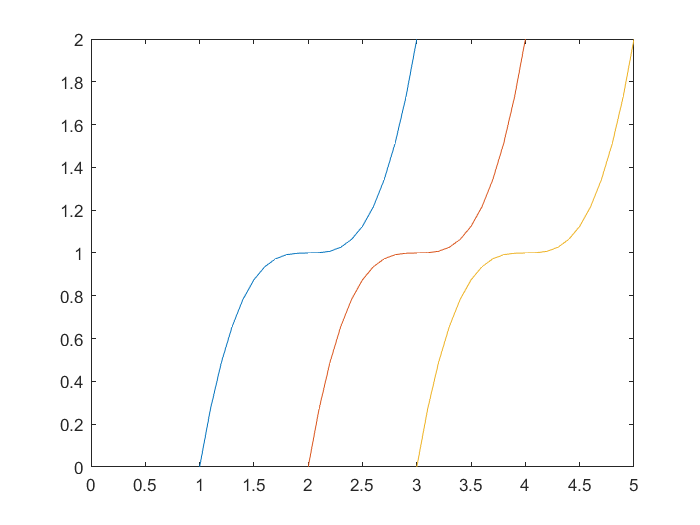


%假设曲线(画出曲线)
x=0:0.1:5;
y=@(x)(x.^3+1);
 plot(x,y(x-2),x,y(x-3),x,y(x-4))
 axis([0,5,0,2])


%  曲线拟合
m=500;
input=zeros(2,m);
input(1,:)=rand(1,m)*5;
input(2,:)=rand(1,m)*2;
 % 样本属性值,在[0,5]×[0,2]中随机地取20个点
 %input为2×20的矩阵
 

 % 样本目标标签值
target=fun(input)

target =      4     4     2     4     4     4     3     1     3     2     4     2     4     4     2     3     3     4     1     4     1     2     3     4     3     1     1     1     1     1     4     1     1     2     3     1     4     1     1     3     1     4     4     1     1     1     1     4     4     4




% newff 函数在2010b 之后已经弃用，现用 feedforwardnet (fitnet) 函数
% net = newff([0 10],[5 1],{'tansig' 'purelin'});
%sigmoid函数也叫Logistic函数，用于隐层神经元输出，取值范围为(0,1)，


% 创建网络2-5-10-4
tranFcn = 'traingda'; % 选择训练函数（学习规则）
hiddenLayer1Size = 5; % 第一层隐含层神经元的数目
hiddenLayer2Size=10;%第二层隐含层神经元的数目
net = feedforwardnet([hiddenLayer1Size,hiddenLayer2Size],tranFcn);



% 网络参数设置
net.layers{1}.transferFcn = 'purelin'; % 第一层隐含层的激活函数
net.layers{2}.transferFcn='purelin';%第二层隐含层的激活函数
net.layers{3}.transferFcn = 'purelin'; % 输出层的激活函数
net.trainparam.show = 50; % 每次循环50次
net.trainParam.epochs = 500; % 最大循环500次
net.trainparam.goal = 0.01; % 期望目标误差最小值


% 初始网络预测
%Configure：配置网络输入和输出,以达到最好的匹配输入和目标数据
net = configure(net,input,target);
pred1 = net(input)

pred1 =     2.0219    1.8834    0.9035    1.4187    2.3164    1.4433    0.2225   -1.1848    1.4543    0.2447    1.4959   -0.1351    0.6164    1.1231   -0.5964   -0.0445    0.4252    1.5849   -2.3292    2.6570   -0.8057    0.3950    1.4529    2.5835    1.5997   -2.7918   -0.8892   -2.3452   -1.1348   -2.2715    1.6454   -1.9421   -2.0572    0.4239   -0.1287   -1.6706    1.2182   -0.9272   -1.2493    1.4409   -1.3683    1.2701    0.9433   -0.7531   -0.7729   -0.3390   -2.8738    1.6656    1.4821    2.0364


%pred1为所对应的input的初始网络预测值





% 训练网络并预测
net = train(net, input, target);
pred2 = net(input)

pred2 =     4.0732    3.7470    2.4833    3.3940    4.1065    3.2653    2.4188    1.4779    3.1452    2.1804    3.7871    2.1975    3.4120    3.1414    2.4507    3.1197    3.2917    3.6101    0.7601    4.0668    1.9461    2.1806    3.0215    4.0371    3.1120    0.7397    1.7216    0.8071    1.6098    0.8440    3.6395    1.3191    0.6278    2.2108    2.8762    1.2601    3.3622    2.0091    1.2236    3.0197    1.3937    3.2708    3.1632    1.9440    1.4772    1.5847    0.7265    3.3056    3.5186    3.5208


%pred2为所对应的input的训练后网络预测值

Error=abs(target-pred2);
fprintf('最大误差为：');

最大误差为：


Max_Error=max(Error)

Max_Error = 1.0895

fprintf('平均误差为：');

平均误差为：

pingjun_Error=(sum(Error))/m

pingjun_Error = 0.3721


save('net.mat','net');       % 将网络net保存为.mat文件，后面可直接调用


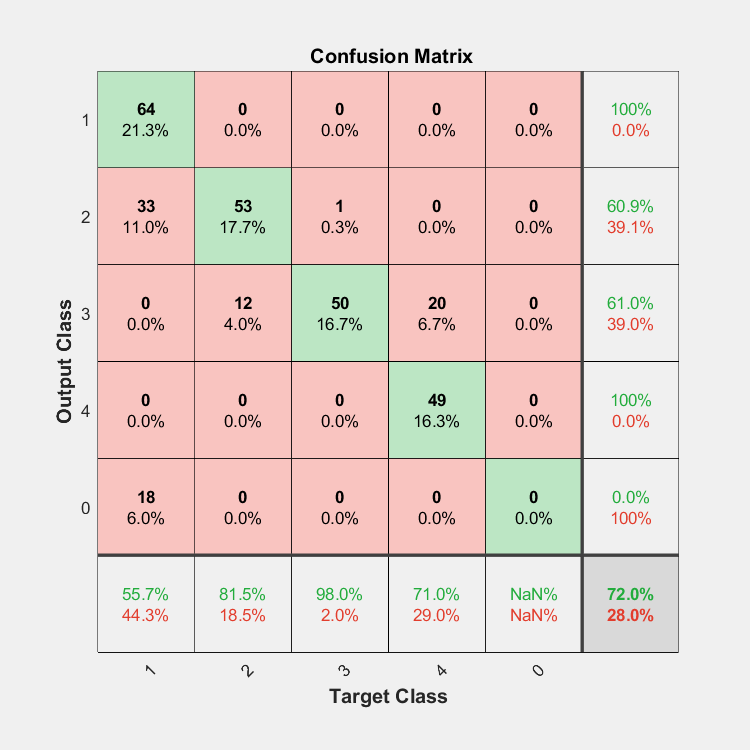

load('net.mat');     % 导入之前保存的网络 

%画图
 m_2=300;
 input_2=zeros(2,m_2);
input_2(1,:)=rand(1,m_2)*5;
input_2(2,:)=rand(1,m_2)*2;
 % 样本属性值,在[0,5]×[0,2]中随机地取m_2个点
 %input为2×m_2的矩阵
 
 % 样本目标标签值
target_2=fun(input_2);
y=sim(net,input_2);
y=round(y);
%画出混淆矩阵
target_2=categorical(target_2);
y=categorical(y);
figure(1)
plotconfusion(target_2,y);         


load('net.mat');     % 导入之前保存的网络
%预测函数
fprintf('请输入测试数据x');

请输入测试数据x

x=[4 1]

x =      4     1


x=x';
fprintf('输出测试结果y');

输出测试结果y

y=sim(net,x)

y = 3.2402